**NAME: ABHISHEK TRIPATHI**

**MATRICULATION NUMBER: 03786108**

**ELEMENTS OF MACHINE LEARNING ASSIGNMENT: VERSION A**

**1. Data Analysis (20 points)Exploratory Data Analysis (EDA):**

% Load dataset
data = readtable('F:\seminar of machine elements exam\Concrete_Data.xls', 'VariableNamingRule', 'preserve');
numColumns = width(data);
disp(['Number of columns in the dataset: ', num2str(numColumns)]);

Number of columns in the dataset: 9


data.Properties.VariableNames = {'Cement', 'Slag', 'FlyAsh', 'Water', 'Superplasticizers','CoarseAggregate','FineAggregate','Age', 'compressive_strength'};
% Check the first few rows to understand its structure
head(data);

    Cement    Slag     FlyAsh    Water    Superplasticizers    CoarseAggregate    FineAggregate    Age    compressive_strength
    ______    _____    ______    _____    _________________    _______________    _____________    ___    ____________________

      540         0      0        162            2.5                 1040               676         28           79.986       
      540         0      0        162            2.5                 1055               676         28           61.887       
    332.5     142.5      0        228              0                  932               594        270            40.27       
    332.5     142.5      0        228              0      


% 2. Correlation Matrix
correlation_matrix = corr(data{:, 1:end}, 'type', 'pearson');
figure;
heatmap(correlation_matrix, 'Title', 'Correlation Matrix of Features');
colorbar;

% 2. Histograms of all the variables
figure;
subplot(3,3,1);
histogram(data.Cement);
title('Cement');
subplot(3,3,2);
histogram(data.Slag);
title('Slag');
subplot(3,3,3);
histogram(data.FlyAsh);
title('FlyAsh');
subplot(3,3,4);
histogram(data.Water);
title('Water');
subplot(3,3,5);
histogram(data.Superplasticizers);
title('Superplasticizers');
subplot(3,3,6);
histogram(data.CoarseAggregate);
title('CoarseAggregate');
subplot(3,3,7);
histogram(data.FineAggregate);
title('FineAggregate');
subplot(3,3,8);
histogram(data.Age);
title('Age');
subplot(3,3,9);
histogram(data.compressive_strength);
title('compressive_strength');
sgtitle('Histogram of all the variables');

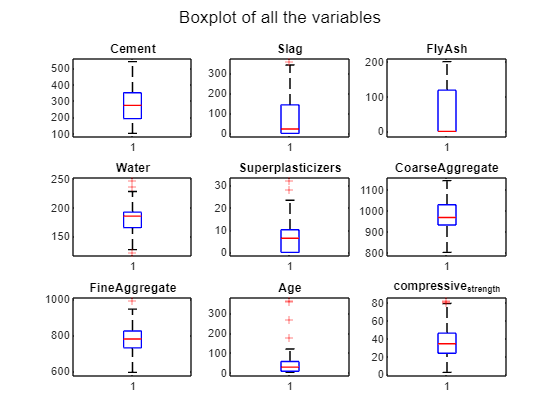

% 2. Boxplot of all the variables
figure;
subplot(3,3,1);
boxplot(data.Cement);
title('Cement');
subplot(3,3,2);
boxplot(data.Slag);
title('Slag');
subplot(3,3,3);
boxplot(data.FlyAsh);
title('FlyAsh');
subplot(3,3,4);
boxplot(data.Water);
title('Water');
subplot(3,3,5);
boxplot(data.Superplasticizers);
title('Superplasticizers');
subplot(3,3,6);
boxplot(data.CoarseAggregate);
title('CoarseAggregate');
subplot(3,3,7);
boxplot(data.FineAggregate);
title('FineAggregate');
subplot(3,3,8);
boxplot(data.Age);
title('Age');
subplot(3,3,9);
boxplot(data.compressive_strength);
title('compressive_strength');
sgtitle('Boxplot of all the variables');

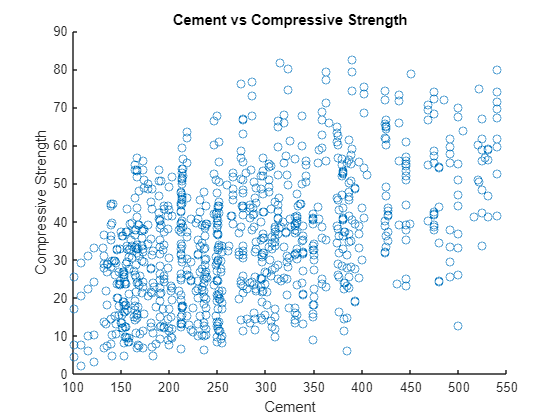

% 3. Scatter plot of Cement (to study correlation with target variable CS)
figure;
scatter(data.Cement, data.compressive_strength);
xlabel('Cement');
ylabel('Compressive Strength');
title('Cement vs Compressive Strength');
hold on

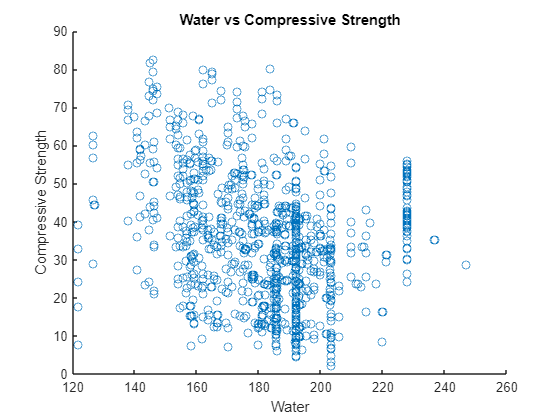

% 3. Scatter plot of Water (to study correlation with target variable CS)
 figure;
 scatter(data.Water, data.compressive_strength);
 xlabel('Water');
 ylabel('Compressive Strength');
 title('Water vs Compressive Strength');

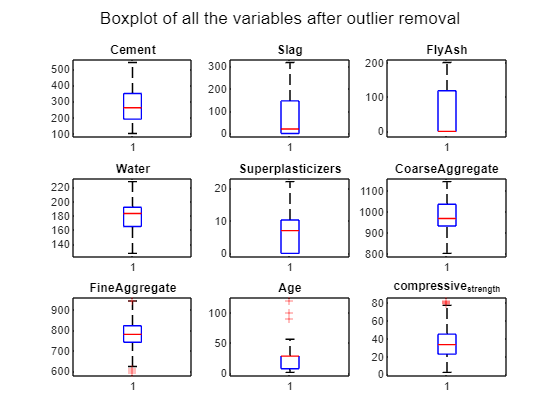


% Outlier detection using Z-scores
z_scores = (data{:, 1:end-1} - mean(data{:, 1:end-1})) ./ std(data{:, 1:end-1});
outliers_z = any(abs(z_scores) > 3, 2);  % threshold of 3
% IQR method
Q1 = prctile(data{:, 1:end-1}, 25);  % First quartile
Q3 = prctile(data{:, 1:end-1}, 75);  % Third quartile
IQR = Q3 - Q1;
outliers_iqr = any(data{:, 1:end-1} < (Q1 - 1.5 * IQR) | data{:, 1:end-1} > (Q3 + 1.5 * IQR), 2);

% Combine Z-score and IQR outliers
outliers_combined = outliers_z | outliers_iqr;  % Either Z-score or IQR is an outlier
outlier_data = data(outliers_combined, :);  % Get all the outlier rows

% Data without outliers
clean_data = data(~outliers_combined, :);  % Remove outliers from the original data
%outlier_data = data(outliers, :);
% 2. Boxplot of all the variables after outlier removal 
figure;
subplot(3,3,1);
boxplot(clean_data.Cement);
title('Cement');
subplot(3,3,2);
boxplot(clean_data.Slag);
title('Slag');
subplot(3,3,3);
boxplot(clean_data.FlyAsh);
title('FlyAsh');
subplot(3,3,4);
boxplot(clean_data.Water);
title('Water');
subplot(3,3,5);
boxplot(clean_data.Superplasticizers);
title('Superplasticizers');
subplot(3,3,6);
boxplot(clean_data.CoarseAggregate);
title('CoarseAggregate');
subplot(3,3,7);
boxplot(clean_data.FineAggregate);
title('FineAggregate');
subplot(3,3,8);
boxplot(clean_data.Age);
title('Age');
subplot(3,3,9);
boxplot(clean_data.compressive_strength);
title('compressive_strength');
sgtitle('Boxplot of all the variables after outlier removal');

.

__________________________________________________________________________________________________________________________________________________________

**2. Supervised Learning (40 points)**

**2.1 Linear Regression (10 points)**

% Splitting the data into training and testing sets with outliers
cv = cvpartition(height(data), 'HoldOut', 0.2);
trainData = data(training(cv), :);
testData = data(test(cv), :);
%disp(trainData.Properties.VariableNames);
% Linear Regression Model with outlier
lm = fitlm(trainData, 'compressive_strength ~ Cement + Slag + FlyAsh + Water+ Superplasticizers + CoarseAggregate + FineAggregate + Age');

% Evaluate on test data
y_pred_o = predict(lm, testData);
y_actual = testData.compressive_strength;

% Performance (R^2, RMSE)
RMSE = sqrt(mean((y_pred_o - y_actual).^2));
R2 = 1 - sum((y_actual - y_pred_o).^2) / sum((y_actual - mean(y_actual)).^2);
fprintf('Linear Regression - RMSE with outliers in the data: %.2f, R2: %.2f\n', RMSE, R2);

Linear Regression - RMSE with outliers in the data: 11.04, R2: 0.54


% Splitting the data into training and testing sets without outliers
cv = cvpartition(height(clean_data), 'HoldOut', 0.2);
trainData = clean_data(training(cv), :);
testData = clean_data(test(cv), :);
%disp(trainData.Properties.VariableNames);

% Linear Regression Model without  outlier
lm = fitlm(trainData, 'compressive_strength ~ Cement + Slag + FlyAsh + Water+ Superplasticizers + CoarseAggregate + FineAggregate + Age');

% Evaluate on test data
y_pred_wo = predict(lm, testData);
y_actual = testData.compressive_strength;

% Performance (R^2, RMSE)
RMSE = sqrt(mean((y_pred_wo - y_actual).^2));
R2 = 1 - sum((y_actual - y_pred_wo).^2) / sum((y_actual - mean(y_actual)).^2);
fprintf('Linear Regression - RMSE without outliers in the data: %.2f, R2: %.2f\n', RMSE, R2);

Linear Regression - RMSE without outliers in the data: 8.16, R2: 0.78


% Plot predicted compressive strength with and without outliers
figure;
plot(1:length(y_pred_o), y_pred_o, 'o-', 'LineWidth', 1.5);
hold on;
plot(1:length(y_pred_wo), y_pred_wo, 's-', 'LineWidth', 1.5);
hold off;

xlabel('Data Point');
ylabel('Predicted Compressive Strength');
title('Comparison of Predicted Compressive Strength');
legend({'With Outliers', 'Without Outliers'}, 'Location', 'Best');
grid on;

________________________________________________________________________________________________________________________________________________________

**2.2 Ridge Regression (15 points)**

Ridge regression applies regularization to prevent overfitting:

% Ridge Regression (L2 regularization) in the dataset
%lambda is regularization parameter
lambda_values = logspace(-5, 5, 20);
% Initialize arrays to store RMSE and R2 values for each lambda
RMSE_values = zeros(length(lambda_values), 1);
R2_values = zeros(length(lambda_values), 1);
for i = 1:length(lambda_values)
X = trainData{:, 1:end-1};%Note that the clean data is now only used following the results of linear ergession model
y = trainData.compressive_strength;%Note that the clean data is now only used following the results of linear ergession model

% Using the fitrlinear function for ridge regression
ridge_model = fitrlinear(X, y, 'Lambda', lambda_values(i));

% Evaluate on test data
X_test = testData{:, 1:end-1};
y_test = testData.compressive_strength;
y_pred_ridge = predict(ridge_model, X_test);

% Performance (RMSE and R2)
RMSE_values(i) = sqrt(mean((y_pred_ridge - y_test).^2));
R2_values(i) = 1 - sum((y_test - y_pred_ridge).^2) / sum((y_test - mean(y_test)).^2);
fprintf('Ridge Regression - lambda: %.2f,RMSE: %.2f, R2: %.2f\n', lambda_values(i), RMSE_values(i), R2_values(i));
end

Ridge Regression - lambda: 0.00,RMSE: 17.15, R2: 0.02
Ridge Regression - lambda: 0.00,RMSE: 17.15, R2: 0.02
Ridge Regression - lambda: 0.00,RMSE: 17.15, R2: 0.02
Ridge Regression - lambda: 0.00,RMSE: 17.15, R2: 0.02
Ridge Regression - lambda: 0.00,RMSE: 17.15, R2: 0.02
Ridge Regression - lambda: 0.00,RMSE: 17.15, R2: 0.02
Ridge Regression - lambda: 0.01,RMSE: 17.15, R2: 0.02
Ridge Regression - lambda: 0.05,RMSE: 17.15, R2: 0.02
Ridge Regression - lambda: 0.16,RMSE: 17.15, R2: 0.02
Ridge Regression - lambda: 0.55,RMSE: 17.15, R2: 0.02
Ridge Regression - lambda: 1.83,RMSE: 17.15, R2: 0.02
Ridge Regression - lambda: 6.16,RMSE: 17.15, R2: 0.02
Ridge Regression - lambda: 20.69,RMSE: 17.15, R2: 0.02
Ridge Regression - lambda: 69.52,RMSE: 17.15, R2: 0.02
Ridge Regression - lambda: 233.57,RMSE: 17.15, R2: 0.02
Ridge Regression - lambda: 784.76,RMSE: 17.15, R2: 0.02
Ridge Regression - lambda: 2636.65,RMSE: 17.15, R2: 0.02
Ridge Regression - lambda: 8858.67,RMSE: 17.15, R2: 0.02
Ridge Regression

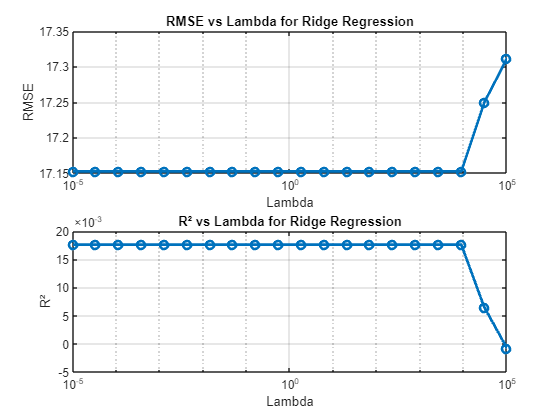


% Plotting RMSE and R2 as a function of lambda
figure;
subplot(2, 1, 1);
semilogx(lambda_values, RMSE_values, '-o', 'LineWidth', 2);
xlabel('Lambda');
ylabel('RMSE');
title('RMSE vs Lambda for Ridge Regression');
grid on;

subplot(2, 1, 2);
semilogx(lambda_values, R2_values, '-o', 'LineWidth', 2);
xlabel('Lambda');
ylabel('R²');
title('R² vs Lambda for Ridge Regression');
grid on;


%Optimal lambda through 5-fold cross-validation
% Defining the range of lambda values to test
lambda_values = logspace(-5, 5, 20);  % Logarithmic scale to cover a wide range

% Initializing arrays to store RMSE and R2 values for each lambda
RMSE_values = zeros(length(lambda_values), 1);
R2_values = zeros(length(lambda_values), 1);

% Performing 5-fold cross-validation for each lambda
k = 5;  % 5-fold cross-validation
cv = cvpartition(height(trainData), 'KFold', k);  % Partition data into 5 folds

for i = 1:length(lambda_values)
    lambda = lambda_values(i);  % Current lambda value
    
    % Initializing variables to store the results of each fold
    RMSE_fold = zeros(k, 1);
    R2_fold = zeros(k, 1);

    for fold = 1:k
        % Splitting data into training and validation sets for the current fold
        train_idx = cv.training(fold);
        val_idx = cv.test(fold);
        
        X_train = trainData{train_idx, 1:end-1};  % Training features
        y_train = trainData.compressive_strength(train_idx);  % Training target
        
        X_val = trainData{val_idx, 1:end-1};  % Validation features
        y_val = trainData.compressive_strength(val_idx);  % Validation target
        
        % Training the model using the current lambda
        ridge_model = fitrlinear(X_train, y_train, 'Lambda', lambda);
        
        % Predict on the validation set
        y_pred_val = predict(ridge_model, X_val);
        
        % Calculate RMSE and R2 for the current fold
        RMSE_fold(fold) = sqrt(mean((y_pred_val - y_val).^2));
        R2_fold(fold) = 1 - sum((y_val - y_pred_val).^2) / sum((y_val - mean(y_val)).^2);
    end
    
    % Average RMSE and R2 over the 5 folds
    RMSE_values(i) = mean(RMSE_fold);
    R2_values(i) = mean(R2_fold);
end

% Find the optimal lambda (the one with the lowest RMSE)
[~, best_lambda_idx] = min(RMSE_values);
optimal_lambda = lambda_values(best_lambda_idx);

% Display the results
fprintf('Optimal lambda using 5-fold CV: %.5f\n', optimal_lambda);

Optimal lambda using 5-fold CV: 0.16238


fprintf('Minimum RMSE: %.2f\n', RMSE_values(best_lambda_idx));

Minimum RMSE: 15.40


fprintf('R2 at optimal lambda: %.2f\n', R2_values(best_lambda_idx));

R2 at optimal lambda: 0.13


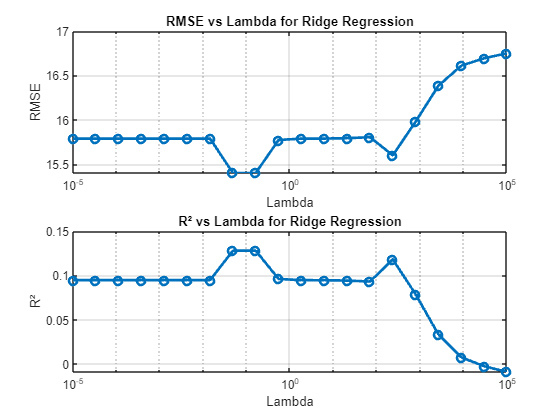


% Plot RMSE and R2 as a function of lambda
figure;
subplot(2, 1, 1);
semilogx(lambda_values, RMSE_values, '-o', 'LineWidth', 2);
xlabel('Lambda');
ylabel('RMSE');
title('RMSE vs Lambda for Ridge Regression');
grid on;

subplot(2, 1, 2);
semilogx(lambda_values, R2_values, '-o', 'LineWidth', 2);
xlabel('Lambda');
ylabel('R²');
title('R² vs Lambda for Ridge Regression');
grid on;

% Ridge Regression (L2 regularization) without outliers in the dataset
%lambda is regularization parameter
lambda_values = logspace(-5, 5, 20);
% Initialize arrays to store RMSE and R2 values for each lambda
RMSE_values = zeros(length(lambda_values), 1);
R2_values = zeros(length(lambda_values), 1);
for i = 1:length(lambda_values)
X = trainData{:, 1:end-1};
y = trainData.compressive_strength;

% Using the fitrlinear function for ridge regression
ridge_model = fitrlinear(X, y, 'Lambda', lambda_values(i));

% Evaluate on test data
X_test = testData{:, 1:end-1};
y_test = testData.compressive_strength;
y_pred_ridge = predict(ridge_model, X_test);

% Performance (RMSE and R2)
RMSE_values(i) = sqrt(mean((y_pred_ridge - y_test).^2));
R2_values(i) = 1 - sum((y_test - y_pred_ridge).^2) / sum((y_test - mean(y_test)).^2);
fprintf('Ridge Regression - lambda: %.2f,RMSE: %.2f, R2: %.2f\n', lambda_values(i), RMSE_values(i), R2_values(i));
end

Ridge Regression - lambda: 0.00,RMSE: 17.15, R2: 0.02
Ridge Regression - lambda: 0.00,RMSE: 17.15, R2: 0.02
Ridge Regression - lambda: 0.00,RMSE: 17.15, R2: 0.02
Ridge Regression - lambda: 0.00,RMSE: 17.15, R2: 0.02
Ridge Regression - lambda: 0.00,RMSE: 17.15, R2: 0.02
Ridge Regression - lambda: 0.00,RMSE: 17.15, R2: 0.02
Ridge Regression - lambda: 0.01,RMSE: 17.15, R2: 0.02
Ridge Regression - lambda: 0.05,RMSE: 17.15, R2: 0.02
Ridge Regression - lambda: 0.16,RMSE: 17.15, R2: 0.02
Ridge Regression - lambda: 0.55,RMSE: 17.15, R2: 0.02
Ridge Regression - lambda: 1.83,RMSE: 17.15, R2: 0.02
Ridge Regression - lambda: 6.16,RMSE: 17.15, R2: 0.02
Ridge Regression - lambda: 20.69,RMSE: 17.15, R2: 0.02
Ridge Regression - lambda: 69.52,RMSE: 17.15, R2: 0.02
Ridge Regression - lambda: 233.57,RMSE: 17.15, R2: 0.02
Ridge Regression - lambda: 784.76,RMSE: 17.15, R2: 0.02
Ridge Regression - lambda: 2636.65,RMSE: 17.15, R2: 0.02
Ridge Regression - lambda: 8858.67,RMSE: 17.15, R2: 0.02
Ridge Regression

**_________________________________________________________________________________________________________________________________________________________**

**2.3 Neural Network Regression (15 points)**

Training neural network for regression:

% A neural network with 2 hidden layers and 10 nodes per layer
net = feedforwardnet([10, 10]);  
net.trainFcn = 'trainlm';  % Levenberg-Marquardt training algorithm

% Training the network
[net, tr] = train(net, X', y');
% Evaluation on test data
y_pred_nn = net(X_test');
RMSE_nn = sqrt(mean((y_pred_nn' - y_test).^2));
R2_nn = 1 - sum((y_test - y_pred_nn').^2) / sum((y_test - mean(y_test)).^2);
fprintf('Neural Network with 2 hidden layers and 10 nodes each - RMSE: %.2f, R2: %.2f\n', RMSE_nn, R2_nn);

Neural Network with 2 hidden layers and 10 nodes each - RMSE: 6.38, R2: 0.86


% A neural network with 3 hidden layers and 15 nodes per layer
net = feedforwardnet([15, 15, 15]);  
net.trainFcn = 'trainlm';  % Levenberg-Marquardt training algorithm

% Training the network
[net, tr] = train(net, X', y');
% Evaluation on test data
y_pred_nn = net(X_test');
RMSE_nn = sqrt(mean((y_pred_nn' - y_test).^2));
R2_nn = 1 - sum((y_test - y_pred_nn').^2) / sum((y_test - mean(y_test)).^2);
fprintf('Neural Network with 3 hidden layers and 15 nodes each - RMSE: %.2f, R2: %.2f\n', RMSE_nn, R2_nn);

Neural Network with 3 hidden layers and 15 nodes each - RMSE: 7.05, R2: 0.83




% A neural network with 3 hidden layers and 10 nodes per layer
net = feedforwardnet([10, 10, 10]);  
net.trainFcn = 'trainlm';  % Levenberg-Marquardt training algorithm

% Training the network
[net, tr] = train(net, X', y');
% Evaluation on test data
y_pred_nn = net(X_test');
RMSE_nn = sqrt(mean((y_pred_nn' - y_test).^2));
R2_nn = 1 - sum((y_test - y_pred_nn').^2) / sum((y_test - mean(y_test)).^2);
fprintf('Neural Network with 3 hidden layers and 10 nodes each - RMSE: %.2f, R2: %.2f\n', RMSE_nn, R2_nn);

Neural Network with 3 hidden layers and 10 nodes each - RMSE: 6.35, R2: 0.87


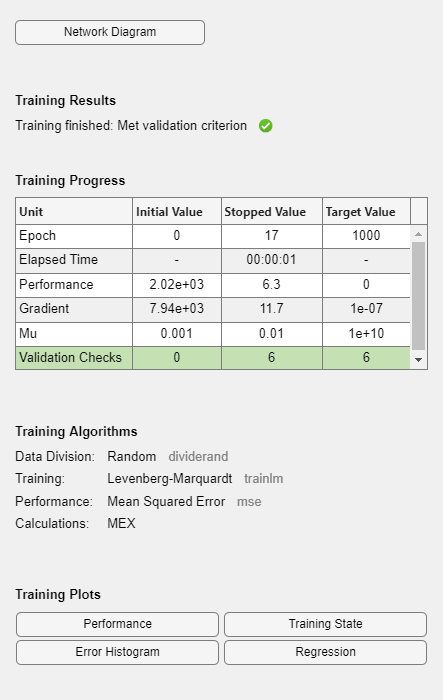


% A neural network with 2 hidden layers and 15 nodes per layer
net = feedforwardnet([15, 15]);  
net.trainFcn = 'trainlm';  % Levenberg-Marquardt training algorithm

% Training the network
[net, tr] = train(net, X', y');

%Evaluation on test data
y_pred_nn = net(X_test');
RMSE_nn = sqrt(mean((y_pred_nn' - y_test).^2));
R2_nn = 1 - sum((y_test - y_pred_nn').^2) / sum((y_test - mean(y_test)).^2);
fprintf('Neural Network with 2 hidden layers and 15 nodes each- RMSE: %.2f, R2: %.2f\n', RMSE_nn, R2_nn);

Neural Network with 2 hidden layers and 15 nodes each- RMSE: 6.58, R2: 0.86


________________________________________________________________________________________________________________________________________________________

**3. Dimensionality Reduction (40 points)**

**3.1 Principal Component Analysis (PCA) (10 points)**

Apply PCA to reduce dimensionality:

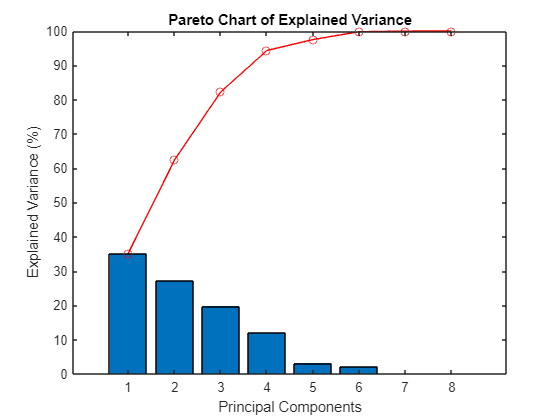



% Performing PCA on the predictor matrix X
[coeff, score, latent, ~, explained] = pca(X);  % coeff: principal components, score: transformed data, latent: eigenvalues, explained: variance explained by each component

% Calculating the cumulative explained variance
cumulativeVariance = cumsum(explained);
% Creating Pareto chart (bar graph of explained variance and cumulative line)
figure;
bar(explained);
hold on;
plot(cumulativeVariance, '-o', 'Color', 'r');
xlabel('Principal Components');
ylabel('Explained Variance (%)');
title('Pareto Chart of Explained Variance');
hold on;
plot(cumulativeVariance, '-o', 'Color', 'r');
xlabel('Principal Components');
ylabel('Explained Variance (%)');
title('Pareto Chart of Explained Variance');
hold off;

disp(latent);%  Eigen values

   1.0e+04 *

    1.2280
    0.9489
    0.6898
    0.4211
    0.1114
    0.0794
    0.0063
    0.0009




% The number of components selected
disp(['Number of PCA components selected: ', num2str(numComponents)]);

Number of PCA components selected: 5


% Selecting the coefficients corresponding to the selected principal components
selectedCoefficients = coeff(:, 1:numComponents);% Google for syntax

% Calculating the importance of each original variable
variableImportance = sum(abs(selectedCoefficients), 2);% Google for syntax

% Ranking the original variables by their importance
[~, sortedIndices] = sort(variableImportance, 'descend');% Google for syntax
% List of original variable names
originalVariableNames = {'Cement', 'Slag', 'FlyAsh', 'Water', 'Superplasticizers', 'CoarseAggregare','FineAggregate','Age' };  

% Sorting the variable names according to their importance
sortedVariableNames = originalVariableNames(sortedIndices);% Google for syntax

% The original variable names contributing to the selected components
disp('Original variables in order of importance:');

Original variables in order of importance:


disp(sortedVariableNames);

    {'FineAggregate'}    {'CoarseAggregare'}    {'FlyAsh'}    {'Slag'}    {'Cement'}    {'Water'}    {'Superplasticizers'}    {'Age'}



for i = 1:numComponents
    fprintf('Principal Component %d: %s\n', i, sortedVariableNames{i});
end

Principal Component 1: FineAggregate
Principal Component 2: CoarseAggregare
Principal Component 3: FlyAsh
Principal Component 4: Slag
Principal Component 5: Cement


**__________________________________________________________________________________________________________________________________________________________**

**3.2 Regression on PCA Latent Variables(15 points)**


% Reducing X to the selected number of components
X_pca = score(:, 1:numComponents);
% Again y is our target variable, compressive strength
% Fitting a linear regression model using the selected PCA components as predictors
lm_pca = fitlm(X_pca, y);
% The results of the fitted model
disp(lm_pca);

Linear regression model:
    y ~ 1 + x1 + x2 + x3 + x4 + x5

Estimated Coefficients:
                   Estimate        SE         tStat       pValue  
                   _________    _________    _______    __________

    (Intercept)         35.1      0.42045     83.482             0
    x1              0.057976    0.0037966      15.27    4.9197e-46
    x2              0.041619    0.0043192     9.6359     8.543e-21
    x3             -0.018641    0.0050656    -3.6798    0.00025012
    x4              0.031537    0.0064833     4.8644    1.3999e-06
    x5               0.27246     0.012604     21.618    6.4963e-81


Number of observations: 755, Error degrees of freedom: 749
Root Mean Squared Error: 11.6
R-squared: 0.526,  Adjusted R-Squared: 0.523
F-st

**_________________________________________________________________________________________________________________________________________________________**

**3.3 Manual Feature Selection (15 points)**

Creating the water-binder ratio feature:

%Creating Water-Binder Ratio
clean_data.water_binder_ratio = clean_data.Water ./ (clean_data.Cement + clean_data.Slag + clean_data.FlyAsh + clean_data.Superplasticizers);

%Removing original individual features and using the new ratio feature
data_reduced = clean_data(:, {'water_binder_ratio','CoarseAggregate','FineAggregate','Age','compressive_strength'});
%The column names of our old dataset
disp(clean_data.Properties.VariableNames);

    {'Cement'}    {'Slag'}    {'FlyAsh'}    {'Water'}    {'Superplasticizers'}    {'CoarseAggregate'}    {'FineAggregate'}    {'Age'}    {'compressive_strength'}    {'water_binder_ratio'}



%The column names of our new dataset of 4 feature and 1 target variable compressive strength
disp(data_reduced.Properties.VariableNames);

    {'water_binder_ratio'}    {'CoarseAggregate'}    {'FineAggregate'}    {'Age'}    {'compressive_strength'}



% Splitting the data into training and testing sets without outliers again
% in new manual feature table
cv = cvpartition(height(data_reduced), 'HoldOut', 0.2);
trainData_reduced = data_reduced(training(cv), :);
testData_reduced= data_reduced(test(cv), :);

% Linear Regression Model without  outlier in of new table
lm_reduced= fitlm(trainData_reduced, 'compressive_strength ~ water_binder_ratio + CoarseAggregate + FineAggregate + Age');

% Evaluating test data
y_pred_reduced = predict(lm_reduced, testData_reduced);
y_actual_reduced = testData_reduced.compressive_strength;

% Performance (R^2, RMSE)
RMSE = sqrt(mean((y_pred_reduced - y_actual_reduced).^2));
R2 = 1 - sum((y_actual_reduced - y_pred_reduced).^2) / sum((y_actual_reduced - mean(y_actual_reduced)).^2);
fprintf('Manual feature Linear Regression - RMSE without outliers of the new data: %.2f, R2: %.2f\n', RMSE, R2);

Manual feature Linear Regression - RMSE without outliers of the new data: 10.10, R2: 0.68


** END OF SCRIPT___________________________________________________________________________________________________________________________________________**